# Emmanuelle Chaigneau

# Serge Charpak Laboratory

# Figure 9 (S2) Dual color ratiometric measurements

# Position of ROIs in vessels : example of veins

## Parameters


FigS2TitleFontsize = 14 ;
FigS2LegendFontsize = 10 ;
FigS2AxisLabelFontsize = 12 ;
FigS2Linewidth = 2 ;

FigureS2 = figure;
FigureS2.Position = [10 10 800 400] ;
FigureS2Layout = tiledlayout(2,4);
FigureS2Layout.Padding = 'tight';

## Load data 

load FRatioVsDepth_ArteriesAndVeins.mat

Depth = FRatioVsDepth_ArteriesAndVeins(:,1) ;

FRatioCenter_Veins = FRatioVsDepth_ArteriesAndVeins(:, [3 5 8 10]) ;
FRatioEdges_Veins = FRatioVsDepth_ArteriesAndVeins(:, [12 14 17 19]) ;


### Extract data of interest

FRatioCenter_Vein1 = FRatioCenter_Veins(:, 1) ;
FRatioCenter_Vein2 = FRatioCenter_Veins(1:19, 2) ;
FRatioCenter_Vein3 = FRatioCenter_Veins(1:17, 3) ;
FRatioCenter_Vein4 = FRatioCenter_Veins(:, 4) ;

FRatioCenter_Vein_Avg = (FRatioCenter_Vein1(1:17) + FRatioCenter_Vein2(1:17) + FRatioCenter_Vein3(1:17) + FRatioCenter_Vein4(1:17))/4 ;

FRatioEdges_Vein1 = FRatioEdges_Veins(:, 1) ;
FRatioEdges_Vein2 = FRatioEdges_Veins(1:19, 2) ;
FRatioEdges_Vein3 = FRatioEdges_Veins(1:17, 3) ;
FRatioEdges_Vein4 = FRatioEdges_Veins(:, 4) ;

FRatioEdges_Vein_Avg = (FRatioEdges_Vein1(1:17) + FRatioEdges_Vein2(1:17) + FRatioEdges_Vein3(1:17) + FRatioEdges_Vein4(1:17)) / 4 ;


## Panel A

## Center focus in veins

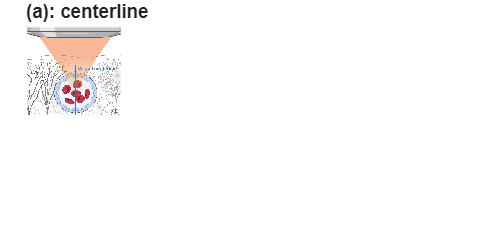

PanelA = nexttile([1 1]) ;

SketchS2A = imread('Fig S2 Large Blood vessel zscan.png');
image(SketchS2A)

PanelA.YColor = [1 1 1] ;
PanelA.XColor = [1 1 1] ;

title('(a): centerline', 'FontSize', FigS2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel C

## Center focus in veins : ROIs + data

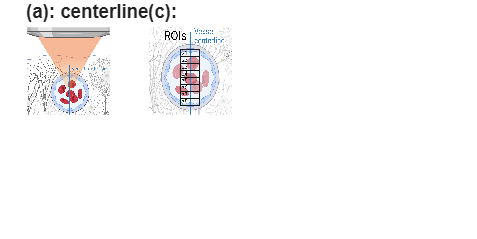

PanelC1 = nexttile([1 1]) ;

SketchS2C = imread('Fig S2 Large Blood vessel zscan center ROIs.png');

image(SketchS2C)

PanelC1.YColor = [1 1 1] ;
PanelC1.XColor = [1 1 1] ;

title('(c): ', 'FontSize', FigS2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

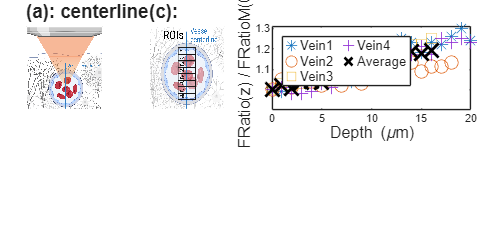

PanelC2 = nexttile([1 2]) ;

hDatazVeinCenter1 = plot(Depth(1:21), FRatioCenter_Vein1,'*');
hold on
hDatazVeinCenter2 = plot(Depth(1:19), FRatioCenter_Vein2,'o');
hDatazVeinCenter3 = plot(Depth(1:17), FRatioCenter_Vein3,'square');
hDatazVeinCenter4 = plot(Depth(:), FRatioCenter_Vein4,'+') ;
hDatazVeinCenterAvg = plot(Depth(1:17), FRatioCenter_Vein_Avg,'x') ;
hold off

hDatazVeinCenter1.MarkerSize = 10 ;
hDatazVeinCenter2.MarkerSize = 10 ;
hDatazVeinCenter3.MarkerSize = 10 ;
hDatazVeinCenter4.MarkerSize = 10 ;
hDatazVeinCenterAvg.MarkerSize = 15 ;
hDatazVeinCenterAvg.Color = [0 0 0] ;
hDatazVeinCenterAvg.LineWidth = 2 ;

legend('Vein1', 'Vein2', 'Vein3', 'Vein4', 'Average', 'Location', 'NorthWest', 'numcolumns', 2, "FontSize", FigS2LegendFontsize);
xlabel("Depth (\mum)", "FontSize", FigS2AxisLabelFontsize)
ylabel("FRatio(z) / FRatioM(0)", "FontSize", FigS2AxisLabelFontsize)
axis([0 20 0.9 1.31]);
xticks([0 5 10 15 20]);
yticks([1 1.1 1.2 1.3]);

## Panel B

## Side focus in veins

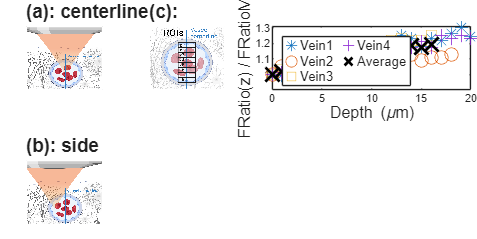

PanelB = nexttile([1 1]) ;

SketchS2B1 = imread('Fig S2 Large Blood vessel zscan side.png');
image(SketchS2B1)

PanelB.YColor = [1 1 1] ;
PanelB.XColor = [1 1 1] ;

title('(b): side', 'FontSize', FigS2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel D

## Side focus in veins ROIs + data

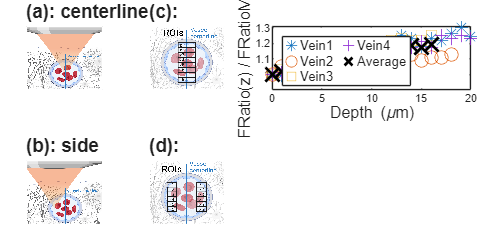

PanelD1 = nexttile([1 1]) ;

SketchS2B2 = imread('Fig S2 Large Blood vessel zscan side ROIs.png');

image(SketchS2B2)

PanelD1.YColor = [1 1 1] ;
PanelD1.XColor = [1 1 1] ;

title('(d): ', 'FontSize', FigS2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

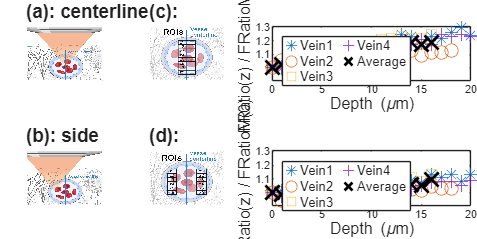

PanelD2 = nexttile([1 2]) ;

hDatazVeinEdge1 = plot(Depth(1:21), FRatioEdges_Vein1,'*');
hold on
hDatazVeinEdge2 = plot(Depth(1:19), FRatioEdges_Vein2,'o');
hDatazVeinEdge3 = plot(Depth(1:17), FRatioEdges_Vein3,'square');
hDatazVeinEdge4 = plot(Depth(:), FRatioEdges_Vein4,'+') ;
hDatazVeinEdgeAvg = plot(Depth(1:17), FRatioEdges_Vein_Avg,'x') ;
hold off

hDatazVeinEdge1.MarkerSize = 10 ;
hDatazVeinEdge1.Color = hDatazVeinCenter1.Color ;
hDatazVeinEdge2.MarkerSize = 10 ;
hDatazVeinEdge2.Color = hDatazVeinCenter2.Color ;
hDatazVeinEdge3.MarkerSize = 10 ;
hDatazVeinEdge3.Color = hDatazVeinCenter3.Color ;
hDatazVeinEdge4.MarkerSize = 10 ;
hDatazVeinEdge4.Color = hDatazVeinCenter4.Color ;
hDatazVeinEdgeAvg.MarkerSize = 15 ;
hDatazVeinEdgeAvg.Color = [0 0 0] ;
hDatazVeinEdgeAvg.LineWidth = 2 ;

legend('Vein1', 'Vein2', 'Vein3', 'Vein4', 'Average', 'Location', 'NorthWest', 'numcolumns', 2, "FontSize", FigS2LegendFontsize);
xlabel("Depth (\mum)", "FontSize", FigS2AxisLabelFontsize)
ylabel("FRatio(z) / FRatioM(0)", "FontSize", FigS2AxisLabelFontsize)
axis([0 20 0.9 1.31]);
xticks([0 5 10 15 20]);
yticks([1 1.1 1.2 1.3]);